%path = [0,0;0,-5;5,0];
path = [0,0;5,0;5,5;10,5];
%path = [0,0;1,0.2;1.8,0.6;2.6,1.0;3.2,2];
%interp1((1:N),path[:1])


N = 30;
% design vector x
% = [torque_Ls, torque_Rs, xs, ys, vs, thetas, thetadots, Tf]
%x0 = [zeros(7*N,1); 1];
x0 = [1*ones(N,1);1*ones(N,1);0.5*ones(N,1);0.5*ones(N,1);1*ones(N,1);0*ones(N,1);0*ones(N,1);1];
costfcn = @(x) x(end);
options = optimoptions('fmincon', 'MaxFunctionEvaluations', 1e5, 'Display', 'iter')

options =   fmincon options:

   Options used by current Algorithm ('interior-point'):
   (Other available algorithms: 'active-set', 'sqp', 'sqp-legacy', 'trust-region-reflective')

   Set properties:
                      Display: 'iter'
       MaxFunctionEvaluations: 100000

   Default properties:
                    Algorithm: 'interior-point'
           BarrierParamUpdate: 'monotone'
               CheckGradients: 0
          ConstraintTolerance: 1.0000e-06
        EnableFeasibilityMode: 0
     FiniteDifferenceStepSize: 'sqrt(eps)'
         FiniteDifferenceType: 'forward'
         HessianApproximation: 'bfgs'
                   HessianFcn: []
           HessianMultiplyFcn: []
                  HonorBounds: 1
                MaxIterations: 1000
               ObjectiveLimit: -1.0000e+20
          OptimalityT

xstar = fmincon(@(x)costfcn_dist(x,path), x0,[],[],[],[],[],[], @(x)nonlcon_path(x,path), options)

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0     212    7.510000e+00    9.500e+00    2.820e-01
    1     424    8.849261e+00    9.286e+00    2.820e-01    2.478e+00
    2     636    1.697025e+01    8.332e+00    1.106e+00    5.516e+00
    3     848    2.459865e+01    7.417e+00    1.973e+00    4.116e+00
    4    1060    2.550274e+01    5.960e+00    5.040e+00    6.366e+00
    5    1272    2.356093e+01    5.765e+00    5.381e+00    7.831e-01
    6    1484    1.019699e+01    4.238e+00    6.587e+00    6.238e+00
    7    1696    9.237771e+00    3.890e+00    5.633e+00    1.266e+00
    8    1908    7.867095e+00    2.553e+00    7.353e+00    4.874e+00
    9    2120    6.457978e+00    2.095e+00    6.756e+00    1.591e+00
   10    2332    4.527634e+00    1.354e+00    4.678e+00    2.725e+00
   11    2544    3.589474e+00    1.002e+00    2.265e+00    1.353e+00
   12    2756    3.253555e+00    6.521e-01    2

xstar =     0.1073
    0.0898
    0.0764
    0.0610
    0.0727
    0.0917
    0.0848
    0.0447
    0.0176
   -0.0138



%options = optimoptions('fmincon', 'MaxFunctionEvaluations', 1e5, 'SpecifyObjectiveGradient', true, 'SpecifyConstraintGradient', true);
%xstar = fmincon(@costfcn_w_grad, x0, [], [], [], [], [], [], @(x)nonlcon_w_grad(x,path), options);

% xstar = it_nonlcon(costfcn, x0, options);

% Extract states from design vectorgit 
[ts, tauL, tauR, x, y, v, th, th_dot] = unpack_design_vector(xstar);
disp(x);

   -0.0000
    0.0000
    0.0975
    0.2767
    0.5253
    0.8294
    1.1995
    1.6529
    2.1835
    2.7547
    3.3419
    3.9165
    4.3729
    4.6830
    4.8498
    4.9948
    4.9948
    4.9948
    4.9948
    4.9948
    5.0000
    5.0000
    5.0167
    4.9449
    5.0422
    6.0224
    7.3146
    8.6408
    9.5475
   10.0000



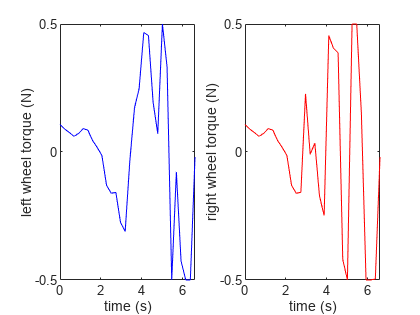


% Plot all states and trajectory
figure
hold on
subplot(1, 2, 1);
plot(ts, tauL, 'b-');
xlabel("time (s)")
ylabel("left wheel torque (N)")

subplot(1, 2, 2);
plot(ts, tauR, 'r-');
xlabel("time (s)")
ylabel("right wheel torque (N)")
hold off

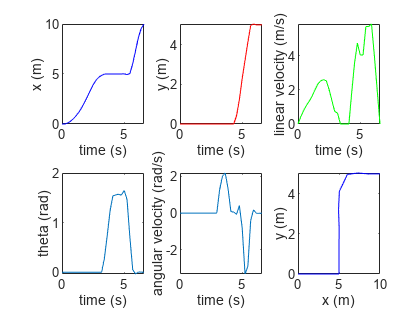


figure
hold on
subplot(2, 3, 1);
plot(ts, x, 'b-');
xlabel("time (s)")
ylabel("x (m)")

subplot(2, 3, 2);
plot(ts, y, 'r-');
xlabel("time (s)")
ylabel("y (m)")

subplot(2, 3, 3);
plot(ts, v, 'g-');
xlabel("time (s)")
ylabel("linear velocity (m/s)")

subplot(2, 3, 4)
plot(ts, th)
xlabel("time (s)")
ylabel("theta (rad)")

subplot(2, 3, 5);
plot(ts, th_dot)
xlabel("time (s)")
ylabel("angular velocity (rad/s)")

subplot(2, 3, 6);
plot(x, y, 'b-');
xlabel("x (m)")
ylabel("y (m)")
hold off

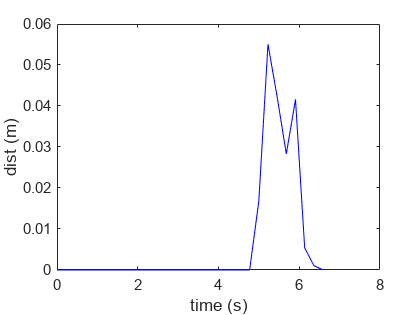

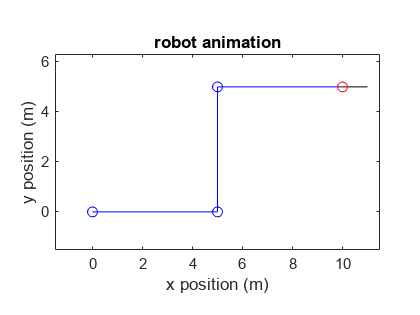


figure
dists = zeros(N,1);
for i = 1:N
    dists(i) = minDistance([x(i),y(i)], path);
end
plot(ts, dists, 'b-')
xlabel("time (s)")
ylabel("dist (m)")

animate_direct_collocation(xstar, path)

% use symbolic toolbox to get cost and constraint function gradients
syms x [7*N+1 1]
matlabFunction(gradient(costfcn(x), x), "File", "costfcn_gradient.m");

[C, Ceq] = nonlcon_path(x,path);

Conversion to logical from sym is not possible.

Error in minDistance>minDistanceSegment (line 18)
    if AB_BE > 0

Error in minDistance (line 4)
      currentDist = minDistanceSegment(x, path(i,:), path(i+1,:));

Error in nonlcon_path

matlabFunction(jacobian(C, x), "File", "nonlcon_c_jacobian.m", "Vars", {x});
matlabFunction(jacobian(Ceq, x), "File", "nonlcon_ceq_jacobian.m", "Vars", {x});

function [f, gradf] = costfcn_w_grad(x)
    f = x(end);
    gradf = costfcn_gradient();
end

function [C, Ceq, GC, GCeq] = nonlcon_w_grad(x,path)
    [C, Ceq] = nonlcon_path(x, path);
    GC = nonlcon_c_jacobian(x)';
    GCeq = nonlcon_ceq_jacobian(x)';
end

function cost = costfcn_dist(d,path)
    N = ((numel(d)-1)/7);
    x = d(2*N+1:3*N);
    y = d(3*N+1:4*N);
    dists = zeros(N,1);
    for i = 1:N
        dists(i) = minDistance([x(i),y(i)], path);
    end
    cost = sum(dists.^2) + 0.01*d(end);
end